## Homework 3: Space Vehicles and Orbital Dynamics

#### Authors:

- Jaume Manresa Rigo (100461930)

- Jorge Cortés de Jesús (100428594)

clear; clc; 
close all;

### Introduction

The objective of this homework is to analyse the trajectory of a satellite orbiting Earth when subjected to the the Earth's attraction and the solar radiation pressure (only present outside of the eclipses).

The satellite is modelled as a sphere of $m=100\;\textrm{kg}$ which deploys a solar sail of $A=20m^2$ that always points towards the sun. Its position at summer solstice is defined by the following oscullating orbital elements

$\zeta_p =\;1800\;\textrm{km}$, $e_s =0\ldotp 1$, $\Omega_s =295$ deg, $i_s =33$ deg, $\omega_s =198$ deg, $\theta =48$ deg.

Where $\zeta_p$ is the altitude at the pericenter. Note that the definition of the semi-major axis in this case becomes $a=\frac{\zeta_p +R_E }{1-e}$.

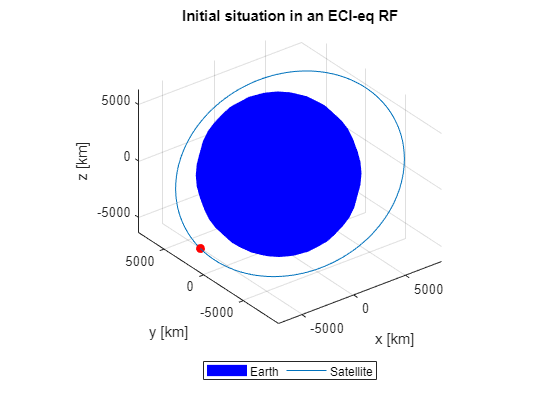

m = 100; % [kg]
A = 20; % [m^2] always points towards the sun
% orbit around earth

rE = 6371; % [km]
muE = 3.986e5; % [km3/s2]
muS = 1.32712440018e11; % [km3/s2]
COE = hw3data();

name = {'Earth';'Satellite'};
title_graph = {'Initial situation in an ECI-eq RF'};
ellipticOrbitPlotter(COE,muE,name,title_graph,rE,1)

The following assumptions will be considered throughout the problem.

- The Earth follows a circular orbit around the Sun. 

- The shade of the Earth is an ideal cylinder.

- The only perturbation that exists on the 2BP motion of the sphere about the Earth is the solar radiation pressure.

As the semi-major axis of the Earth's circular orbit ($a_{\oplus }$), the value of 1 au will be selected.

e_e = 0; % we assume circular orbit around the sun
a_e = 149597870.7; % [km] 

### Part (a)

To begin, a change of reference frames will be carried out. It is easy to see that if the solar radiation pressure is to be considered, the most appropriate and clear way to work will be in an ecliptic ECI reference frame. 

To perform this change, the axial tilt of the earth must be taken into account. Numerous soures state that it follows a cyclic distribution, for 40000 years  in a range of $\left\lbrack 22\ldotp 1,24\ldotp 5\right\rbrack$º. The current one is $\varepsilon =23\ldotp 44º$ and will be the one employed in the calculations.

obliquity = deg2rad(23.44); % [rad]

By definition, the ecliptic reference frame still maintains the vernal equinox as the direction of its x-axis, whereas the z axis points in the direction of the angular momentum vector of Earth's orbit, i.e. it is perpendicular to the orbital plane. A simple rotation matrix will then be introduced to change from ECI-eq ($S_o$) to ECI-ec ($S_1$).


$$\left\lbrack {}^{\;}_1R^{\;}_0\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\varepsilon \right) & \sin \left(\varepsilon \right)\\
0 & -\sin \left(\varepsilon \right) & \cos \left(\varepsilon \right)
\end{array}\right\rbrack$$


${\overrightarrow{r} }_1 =\left\lbrack {}^{\;}_1R^{\;}_0\right\rbrack \cdot {\overrightarrow{r} }_0$;        ${\overrightarrow{v} }_1 =\left\lbrack {}^{\;}_1R^{\;}_0\right\rbrack \cdot {\overrightarrow{v} }_0$

To calculate the initial orbit parameters of the satellite in the ECI-ec reference frame, this procedure is implemented into a function called *EQ2EC*. The functions developed in the previous homeworks to calculate the position and velocity vectors from the COE and viceversa will be used.

The procedure will be structured in three parts. Firstly, the *COE2rv* function will be used to optain the position and velocity vectors from the given OOEs in the ECI-eq reference frame. 

Then, the function *EQ2EC* will be used to change these vectors to the ECI-ec reference frame. Finally, *rv2COE* will be used to obtain the initial orbital parameters in the desired reference frame. Note that the semi-major axis and the eccentricity remain constant regardless of the selected frame.

[r0,v0] = COE2rv(COE(1),COE(2),COE(3),COE(4),COE(5),COE(6),muE);

[r1_ec,v1_ec] = EQ2EC(r0,v0,obliquity);

[a_ec,e_ec,i_ec,raan_ec,omega_ec,theta_ec] = rv2COE(muE,r1_ec,v1_ec);

i_ec = rad2deg(i_ec);
raan_ec = rad2deg(raan_ec);
omega_ec = rad2deg(omega_ec);
theta_ec = rad2deg(theta_ec);

### Part (b)

In this section a function *F = srp(t)* that calculates the force ($F$) exherted on the sail due to the radiation pressure at a time ($t$**)** since the solstice will be developed. For now, the appearance of eclipses will not be implemented. The reflection coefficient is assumed to be maximal ($R=1$).

As the only input required will be the time, the function will have built-in all data necessary about the positions of both the satellite and Earth.

The function will have built-in the procedure explained in part (a) with the peculiarity that, as the true anomaly changes with time, a correction wil be made to account for the different positions of the satellite. The period of both the orbits of the Earth and the satellite will first be calculated.

$\tau_s =2\pi \sqrt{\frac{{a_s }^3 }{\mu_e }}$;         $\tau_{\oplus } =2\pi \sqrt{\frac{{a_{\oplus } }^3 }{\mu_{\oplus } }}$

tau = 2*pi*sqrt(COE(1)^3/muE);
tau_e = 2*pi*sqrt(a_e^3/muS);

Where the subindex *s* refers to the satellite and *e* to the Earth. Then, the mean motion of both bodies is easily computed.

$n_s =\frac{2\pi }{\tau_s }$;         $n_{\oplus } =\frac{2\pi }{\tau_{\oplus } }$

n = 2*pi/tau;
n_e = 2*pi / tau_e;

Then, the true anomaly will be:


$$\theta \left(t\right)=\theta_o +n_s \cdot t$$


Then, the position and velocity vectors of the satellite in the ecliptical ECI reference frame are obtained with the help of the previously discussed functions.

Since the problem relies in the interaction between the sun and the satellite, it is conveniente to change the origin of coordinates from the Earth to the Sun ($S_2$). In order to do this, the position of the Earth relative to the Sun must be obtained first. Given the assumption of a circular orbit, and that its orbital period is already calculated, the position vector is calculated as follows.


$${\overrightarrow{r} }_2^{\oplus } =\left\lbrack \begin{array}{ccc}
-\sin \left(n_{\oplus } \cdot t\right) & \cos \left(n_{\oplus } \cdot t\right) & 0
\end{array}\right\rbrack \cdot a_e$$


Note that the signs are selected to represent the counterclockwise motion of the Earth around the Sun. Geometrically, it is now possible to obtain the vector that goes from the Sun to the satellite (${\overrightarrow{r} }_2^s$),


$${\overrightarrow{r} }_2^s ={\overrightarrow{r} }_1^s +{\overrightarrow{r} }_2^{\oplus }$$


Once the change to an ecliptical Sun-centric inertial reference frame is completed, the expression of the force due to solar radiation pressure, as indicated in the notes, can be introduced:

$\overrightarrow{F^{\oplus } } =-P_{\odot } \textrm{Acos}\phi \left\lbrack \left(1-R\right)\overrightarrow{u_{\odot } } +2\textrm{Rcos}\left(\phi \right)\overrightarrow{n} \right\rbrack$,

where $P_{\odot } =4\ldotp 560\cdot {10}^{-6} \;\frac{N}{m^2 }$ is the average flux of momentum per unit time and unit area whereas $\overrightarrow{u_{\odot } }$ and $\overrightarrow{n}$ are the unit sun vector which points to the sun and an outward-pointing vector normal to the surface of the solar sail respectively. The angle between these two vectors is $\phi$.

It is trivial to calculate the first vector,


$$\overrightarrow{u_{\odot } } =\frac{-{\overrightarrow{r} }_2^s }{\left|{\overrightarrow{r} }_2^s \right|}$$


This satellite has the particualrity of having its solar sail is always pointing to the Sun. In this case, $\overrightarrow{u_{\odot } } =\overrightarrow{n}$and the angle between them will be zero $\phi =0º$.

Now, the force exherted on the satellite can be computed.

In the following plot, the components of the position vector of the satellite in $S_2$ will be shown. As the orbit of the satellite is very small when compared to th e orbit of the Earth, this plot can also be used to verify the initial conditions and the correct implementation of the characteristics of the counterclockwise motion of the Earth in a ecliptical ECI. Note that these plots are merely used to illustrate in a graphical way the results obtained so far. When the force, satellite and Earth's attraction is implemented, these values may change. 

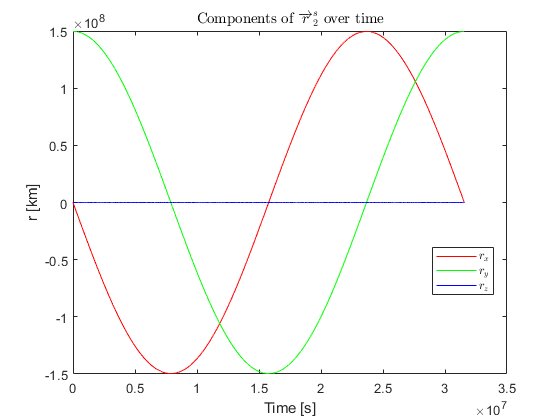

t_values = linspace(0, tau_e, 100000);

for i = 1:length(t_values)
    r_earth(:,i) = [-sin(n_e*t_values(i)), cos(n_e*t_values(i)), 0] * a_e;
    [r0, v0] = COE2rv(COE(1), COE(2), COE(3), COE(4), COE(5), COE(6) + n*t_values(i),muE);
    [r1_ec(:,i),~] = EQ2EC(r0,v0,obliquity);
    r_sat_sun(:,i) = r1_ec(:,i) + r_earth(:,i);
end

figure;
plot(t_values, r_sat_sun(1, :), 'r', t_values, r_sat_sun(2, :), 'g', t_values, r_sat_sun(3, :), 'b');
title('Components of $\overrightarrow{r}^{s}_{2}$ over time','Interpreter','Latex');
xlabel('Time [s]');
ylabel('r [km]');
legend('$r_x$', '$r_y$', '$r_z$','Location','best','Interpreter','Latex');

To continue, the helix that the satellite describes along the Earth's orbit can be appreciated. To properly appreciate the motion, the time span has been greatly reduced.

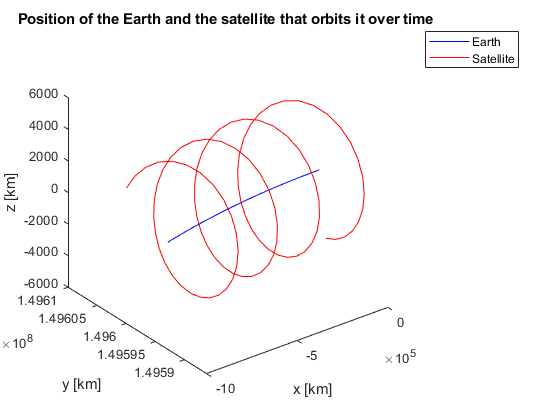

figure;
plot3(r_earth(1, 1:100), r_earth(2, 1:100),r_earth(3, 1:100), 'b');
hold on
plot3(r_sat_sun(1, 1:100), r_sat_sun(2, 1:100),r_sat_sun(3, 1:100), 'r');
title('Position of the Earth and the satellite that orbits it over time ');
legend('Earth','Satellite');
xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');

### Part (c)

The solar radiation pressure only affects the satellite when there is an exposure to the Sun. However, throughout the orbit it describes around the Earth, there are phases of eclipse, i.e. the Earth blocks the sun rays and the satellite finds itself in a region of darkness. As stated before, this eclipse will be modelled as an ideal cylinder.

To check if the satellite is currently in an eclipse region, a function *flag = eclipse(r,t)* will be implemented, where *r* is the position vector of the satellite in $S_1$ (${\overrightarrow{r} }_1^s$), *t* is the time elapsed since the summer solstice and* flag *is a boolean value that returns a *true* value if the satellite is indeed inside the eclipse and *false* otherwise.

When this function is called, the value of ${\overrightarrow{r} }_2^{\oplus }$ and ${\overrightarrow{r} }_2^s$ are quickly calculated in the same way as in the *srp* function. Two additional criteria will be now introduced to verify the eclipse condition.

- $\left|\varphi \right|<\left|\varphi_{\textrm{crit}} \right|$. The absolute value of the angle between ${\overrightarrow{r} }_2^s$ and ${\overrightarrow{r} }_2^{\oplus }$, $\varphi$, must be lower than the absolute value of the critical angle $\varphi_{\textrm{crit}} =\left|\textrm{atan}\left(\frac{R_E }{a_e }\right)\right|$, where $R_E$ is the radius of the Earth. This condition ensures that the satellite will be within the potential region in which there is an eclipse region since $\varphi_{\textrm{crit}}$ marks the boundary of the cylinder. Note that this condition alone is not enough to say that if the satellite is between the Sun and Earth or behind the Earth.

- $\cos \left(\varphi \right)\left|{\overrightarrow{r} }_2^s \right|>a_e$. The magnitude of the projection of ${\overrightarrow{r} }_2^s$ must be higher than the value of the semi-major axis of the Earth's orbit, imposing that the satellite is further than the center of the Earth and effectively ensuring the satellite is in the eclipse.

To implement these constraints, the angle $\varphi$ will be first calculated


$$\left|\varphi \right|=\left|\textrm{acos}\left(\frac{{\overrightarrow{r} }_2^s \cdot {\overrightarrow{r} }_2^{\oplus } }{\left|{\overrightarrow{r} }_2^s \right|\left|{\overrightarrow{r} }_2^{\oplus } \right|}\right)\right|$$


The remaining part of the function code simply involves correctly implementing the *if* statement that sets the *flag* value.

### Part (d)

A

### Part (e)

A

### Conclusion and Remarks

A